# PUSCH资源映射

PUSCH（物理上行共享信道）是一种用于传输上行数据的特定信道。PUSCH关键信息如下：

- 资源分配（符号数、RB数）；

- AdaptIve Modulation and coding；

- TPMI码本选择；

- 波形选择；

- DMRS序列选择。

## 1 载波配置

clear;
clc;
close all;

% Carrier configuration
carrier = nrCarrierConfig;
carrier.NCellID = 2;                    % Cell identity
carrier.SubcarrierSpacing = 30;         % Carrier/BWP Subcarrier spacing
carrier.CyclicPrefix = 'normal';        % Cyclic prefix
carrier.NSlot      = 0;                 % Slot counter
carrier.NFrame     = 0;                 % Frame counter
carrier.NStartGrid = 0;                 % Carrier offset
carrier.NSizeGrid  = 51;                % Size of carrier in RB

## 2 PUSCH资源配置

**(1) Transform precoding**

去使能使能预编码，PUSCH和DMRS采用伪随机序列。

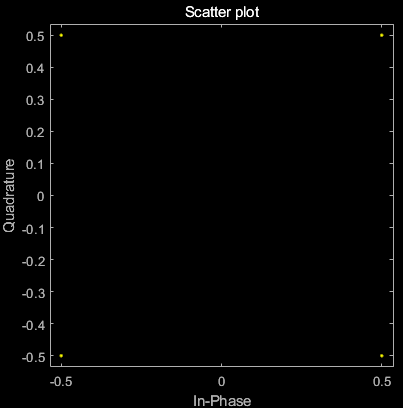  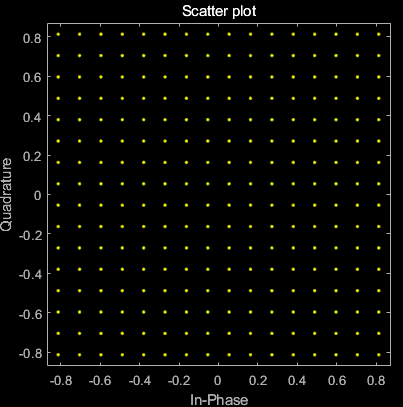

                                       DMRS星座图                                                                                    PUSCH星座图

使能预编码，PUSCH和DMRS采用Low PAPR序列。

- 只支持1流；

- RB需要满足235原则；

- 只支持dmrs-Type=1；

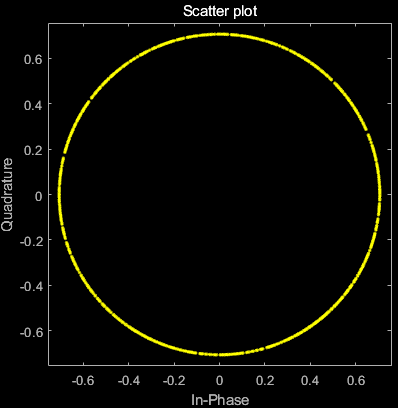  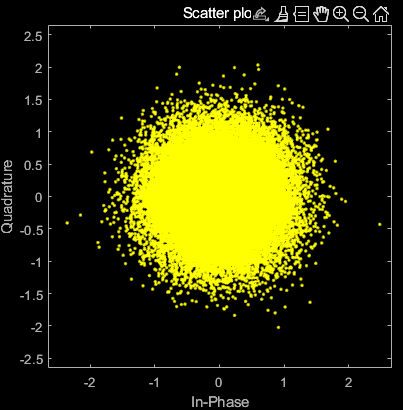

                                       DMRS星座图                                                                                    PUSCH星座图

**(2) Precoding**

For non-codebook-based transmission, the precoding matrix  equals the identity matrix.

For codebook-based transmission, the precoding matrix  is given by  for single-layer transmission on a single antenna port, otherwise by Tables as  follow with the TPMI index. 

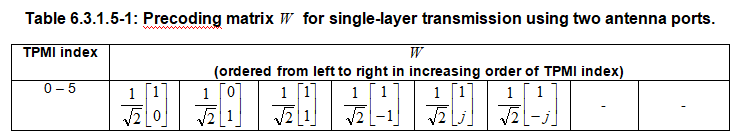

    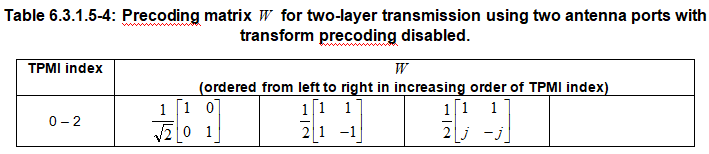

pusch = nrPUSCHConfig;
pusch.NStartBWP = [];
pusch.NSizeBWP = [];
pusch.Modulation = '256QAM';
pusch.NumLayers = 1;
pusch.MappingType = 'A';
pusch.SymbolAllocation = [0 14];        % [S L]
pusch.PRBSet = 0:9;
pusch.TransformPrecoding = 1;           % 0:Disable transform precoding  1:Enable transform precoding
pusch.TransmissionScheme = 'codebook';  % 'nonCodebook' or 'codebook'
pusch.NumAntennaPorts = 2;              % 1/2/4, NumAntennaPorts >= NumLayers
pusch.TPMI = 4;                         % Transmitted precoding matrix indicator, specified as an integer from 0 to 27
pusch.FrequencyHopping = 'neither';
pusch.NID = [];
pusch.RNTI = 1;

disp(pusch)

  nrPUSCHConfig - 属性:

              NSizeBWP: []
             NStartBWP: []
            Modulation: '256QAM'
             NumLayers: 1
           MappingType: 'A'
      SymbolAllocation: [0 14]
                PRBSet: [0 1 2 3 4 5 6 7 8 9]
    TransformPrecoding: 1
    TransmissionScheme: 'codebook'
       NumAntennaPorts: 2
                  TPMI: 4
      FrequencyHopping: 'neither'
     SecondHopStartPRB: 1
         BetaOffsetACK: 20
        BetaOffsetCSI1: 6.2500
        BetaOffsetCSI2: 6.2500
            UCIScaling: 1
                   NID: []
                  RNTI: 1
                NRAPID: []
                  DMRS: [1×1 nrPUSCHDMRSConfig]
            EnablePTRS: 0
                  PTRS: [1×1 nrPUSCHPTRSConfig]



## 3 PUSCH DMRS配置

### 3.1 DMRS port选择

**（1）DFT波形**

**（2）CP波形**

### 3.2 **low PAPR DM-RS**

DFT波形会生效low PAPR DM-RS，配置DMRSUplinkR16也会生效low PAPR DM-RS。

dmrs = nrPUSCHDMRSConfig; 
dmrs.DMRSTypeAPosition = 2;
dmrs.DMRSConfigurationType = 1;
dmrs.DMRSAdditionalPosition = 1;
dmrs.DMRSLength = 1;
dmrs.DMRSPortSet = [];                     % Num of DMRSPortSets must be equal to NumLayers.
dmrs.NumCDMGroupsWithoutData = 2;
dmrs.DMRSUplinkR16 = 0;                    % 1:Enable the use of low PAPR DM-RS.
dmrs.DMRSUplinkTransformPrecodingR16 = 0;  % 1:Enable the use of low PAPR DM-RS for PUSCH with pi/2 BPSK modulation.
pusch.DMRS = dmrs;

disp(dmrs)

  nrPUSCHDMRSConfig - 属性:

              DMRSConfigurationType: 1
                  DMRSTypeAPosition: 2
             DMRSAdditionalPosition: 1
                         DMRSLength: 1
                    CustomSymbolSet: []
                        DMRSPortSet: []
                           NIDNSCID: []
                              NSCID: 0
                       GroupHopping: 0
                    SequenceHopping: 0
                              NRSID: []
            NumCDMGroupsWithoutData: 2
                      DMRSUplinkR16: 0
    DMRSUplinkTransformPrecodingR16: 0

   Read-only properties:
                          CDMGroups: 0
                        DeltaShifts: 0
                   FrequencyWeights: [2×1 double]
                        TimeWeights: [2×1 double]
            DMRSSubcarrierLocations: [6×1 double]
                         CDMLengths: [1 1]



## 4 资源映射

% Generate PUSCH DM-RS symbols
symDmrs = nrPUSCHDMRS(carrier,pusch);
indDmrs = nrPUSCHDMRSIndices(carrier,pusch);

% Generate PUSCH symbols
[indPusch,info] = nrPUSCHIndices(carrier,pusch);
numDataBits = info.G;
cws = randi([0 1],numDataBits,1);
symPusch = nrPUSCH(carrier,pusch,cws);

carrierGrid = nrResourceGrid(carrier,pusch.NumAntennaPorts);
carrierGrid(indDmrs) = symDmrs;
carrierGrid(indPusch) = symPusch;

disp(info)

                G: 11520
               Gd: 1440
        NREPerPRB: 144
    DMRSSymbolSet: [2 11]
    PTRSSymbolSet: [1×0 double]



**对资源网格画图显示**

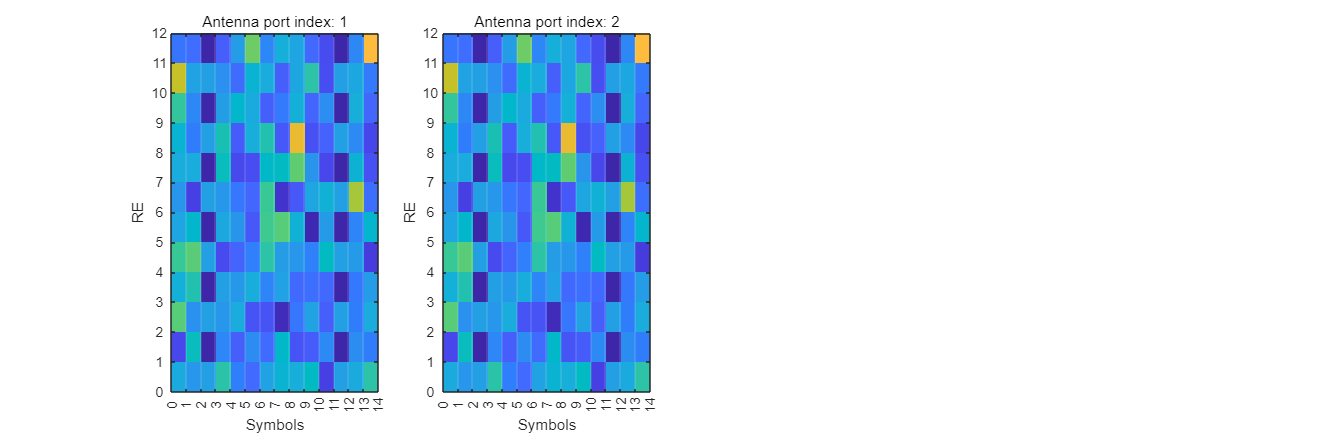

fig = figure;
fig.Position = [100 100 1200 400];
for idx = 1:pusch.NumAntennaPorts
    subplot(1,4,idx)
    imagesc(abs(carrierGrid(:,:,idx)));
    set(gca, 'XLim', [0.5, 14.5]);
    set(gca, 'XTick', (0:14)+0.5);
    set(gca, 'XTickLabel', (0:14));
    set(gca, 'XGrid', 'on');
    set(gca, 'GridColor', 'white');
    set(gca, 'YDir', 'normal');
    set(gca, 'YLim', [0.5, 12.5]);
    set(gca, 'YTick', (0:12)+0.5);
    set(gca, 'YTickLabel', (0:12));
    xlabel('Symbols');
    ylabel('RE');
    title(['Antenna port index: ',num2str(idx)])
end

## 5 OFDM调制

[txWave,~] = nrOFDMModulate(carrier,carrierGrid);

PAPR = table();
for idx = 1:pusch.NumAntennaPorts
    PAPR{idx,1} = getPAPR(txWave(:,idx));
    PAPR.Properties.RowNames{idx} = ['Antenna Port:', num2str(idx)];
end
PAPR.Properties.VariableNames{1} = 'PAPR'

PAPR = 2×1 table
                       PAPR 
                      ______

    Antenna Port:1    2.6204
    Antenna Port:2    2.6204


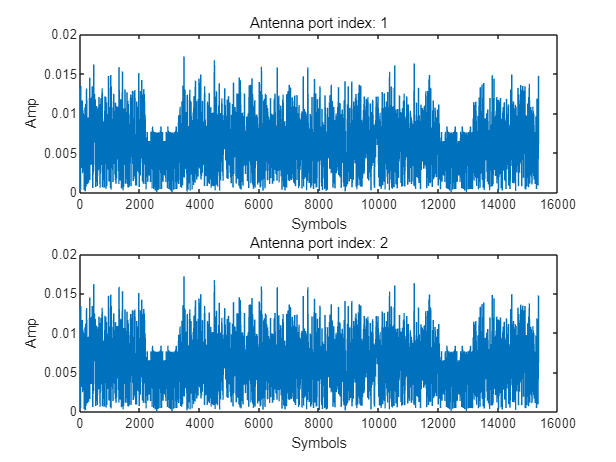

figure
for idx = 1:pusch.NumAntennaPorts
    subplot(2,1,idx)
    plot(abs(txWave(:,idx)));
%     set(gca, 'XLim', [0.5, 14.5]);
%     set(gca, 'XTick', (0:14)+0.5);
%     set(gca, 'XTickLabel', (0:14));
%     set(gca, 'XGrid', 'on');
%     set(gca, 'GridColor', 'white');
    xlabel('Symbols');
    ylabel('Amp');
    title(['Antenna port index: ',num2str(idx)])
end

function PAR = getPAPR(signal)

    peak_value = max(abs(signal));
    average_value = mean(abs(signal));
    PAR = peak_value / average_value;

end